TRY1
% % Given Data
% S0 = [0.1, 0.5, 1, 2, 3, 5, 7, 10, 13, 16, 18, 20, 24]; % F-6-P Concentration (mM)
% V0 = [0.1, 1.1, 3, 9, 15, 22, 26, 28, 29, 29.5, 30, 30, 30]; % Velocity (μM/s)
% 
% % Plot the data
% figure;
% plot(S0, V0, 'o-', 'LineWidth', 2);
% xlabel('[F-6-P] (mM)');
% ylabel('Velocity of production of F-1,6-BP (μM/s)');
% title('Enzyme Kinetics of PFK-1');
% grid on;
% % Convert to proper units for calculation
% S0 = S0 * 1e-3;   % Convert mM to M (optional, depending on context)
% V0 = V0;          % Velocity in μM/s
% 
% % Lineweaver-Burk Plot
% inverse_V0 = 1 ./ V0;
% inverse_S0 = 1 ./ S0;
% 
% % Perform linear regression to get slope and intercept
% p = polyfit(inverse_S0, inverse_V0, 1);
% slope = p(1);
% intercept = p(2);
% 
% % Calculate Km and Vmax from slope and intercept
% Vmax = 1 / intercept;
% Km = slope * Vmax;
% 
% disp(['Km: ', num2str(Km), ' mM']);
% disp(['Vmax: ', num2str(Vmax), ' μM/s']);
% 
% % Plotting Lineweaver-Burk Plot
% figure;
% plot(inverse_S0, inverse_V0, 'o');
% hold on;
% plot(inverse_S0, polyval(p, inverse_S0), '-');
% xlabel('1/[S] (1/mM)');
% ylabel('1/V (1/(μM/s))');
% title('Lineweaver-Burk Plot');
% legend('Data', 'Fit');
% grid on;





TRY2
% Given Data
S0 = [0.1, 0.5, 1, 2, 3, 5, 7, 10, 13, 16, 18, 20, 24]; % F-6-P Concentration (mM)
V0 = [0.1, 1.1, 3, 9, 15, 22, 26, 28, 29, 29.5, 30, 30, 30]; % Velocity (μM/s)

% Estimate Vmax (from data it appears to be around 30 μM/s)
Vmax = 30; 

% Transform Data for Hill Plot
log_S0 = log10(S0); 
log_V_over_Vmax_minus_V = log10(V0 ./ (Vmax - V0));

% Perform linear regression to get slope (n) and intercept
p = polyfit(log_S0, log_V_over_Vmax_minus_V, 1);
n = p(1);
log_KH = p(2);

% Calculate Hill constant KH
KH = 10^(-log_KH / n);

disp(['Hill coefficient (n): ', num2str(n)]);

Hill coefficient (n): NaN


disp(['Hill constant (K_H): ', num2str(KH), ' mM']);

Hill constant (K_H): NaN mM


disp(['Vmax: ', num2str(Vmax), ' μM/s']);

Vmax: 30 μM/s


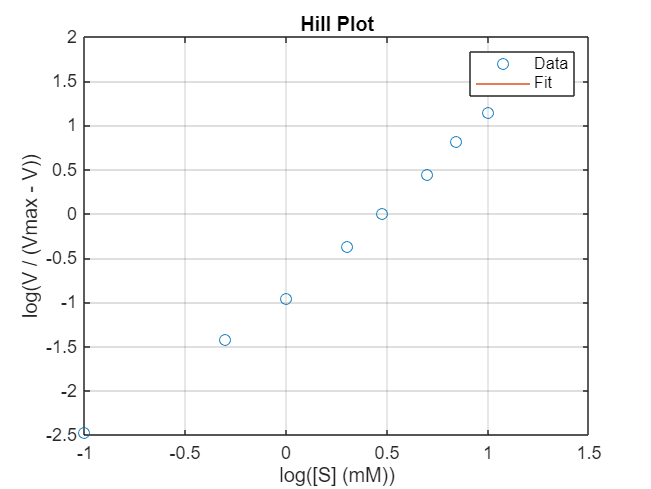


% Plotting Hill Plot
figure;
plot(log_S0, log_V_over_Vmax_minus_V, 'o');
hold on;
plot(log_S0, polyval(p, log_S0), '-');
xlabel('log([S] (mM))');
ylabel('log(V / (Vmax - V))');
title('Hill Plot');
legend('Data', 'Fit');
grid on;